k=6;

%Compute values for topology
assert(mod(k,2)==0,'Error, k must be an even number.')
core=(k/2)^2;
%pods=core/2;
aggregation=core*2;
pods=k;
ecm=k/2;%host per aggregation
variable_names_node_table = {'EndNodes';'Xpoint';'Ypoint';'Layer'};

%Compute values for plotting
differenceX=1;
startX=0; %Compute startX as the difference between total width and width of present layer divided by 2.
differenceY=1;
startY=4;
width=aggregation*ecm*differenceX;

%Preallocation
h=aggregation*2+aggregation*ecm+core+1;
endnodes = cell(h, 1);
Xpoint(h,1)=1;
Ypoint(h,1)=1;
layern(h,1)=1;
edges(core+3*aggregation*ecm,2)=1;

%Internet layer
Xpoint(1,1)=width/2;
Ypoint(1,1)=startY;
layern(1)=0;
endnodes{1}='IT';

%Ypoint=zeros(h,1)+ones(h-aggregation*host_per_aggregation,1)+ones(core+1+aggregation,1)+ones(core+1,1)+ones(1,1)

%Core layer
startX=(width-(core-1)*differenceX)/2;
startY=startY-1;
for i=1:core
    Ypoint(i+1,1)=startY;
    Xpoint(i+1,1)=startX+differenceX*(i-1);
    layern(i+1)=1;
    endnodes{i+1} = strcat('C', num2str(i));
    edges(i,1)= 1;
    edges(i,2)= i+1;
end

%Aggregation layer
posedge=i;
posnode=i+1;
startY=startY-1;
startX=(width-(aggregation-1)*differenceX)/2;
count=1;
countpod=1;
for i=1:aggregation
    Ypoint(posnode+i,1)=startY;
    layern(posnode+i,1)=2;
    Xpoint(posnode+i,1)=startX+differenceX*(i-1);
    endnodes{posnode+i} = strcat('A', num2str(i));
    if i>countpod*ecm
        countpod=countpod+1;
    end
    for j=2:ecm+1
        edges(posedge+count,1)=posnode+i;
        edges(posedge+count,2)= j+((i-(countpod-1)*ecm)-1)*ecm;
        count=count+1;
    end
end

%Edge layer
posedge=posedge+count-1;
posagg=posnode;
posnode=posnode+i;
startY=startY-1;
startX=(width-(aggregation-1)*differenceX)/2;
count=1;
countpod=1;
for i=1:aggregation
    Ypoint(posnode+i,1)=startY;
    layern(posnode+i,1)=3;
    Xpoint(posnode+i,1)=startX+differenceX*(i-1);
    endnodes{posnode+i} = strcat('E', num2str(i));
    %extra=int32(i/ecm)-1;
    if i>countpod*ecm
        countpod=countpod+1;
    end
    for j=1:ecm
        edges(posedge+count,1)=posnode+i;
        edges(posedge+count,2)= posagg+j+(countpod-1)*ecm;
        count=count+1;
    end
end

%Host layer
posedge=posedge+count-1;
posnode=posnode+i;
posagg=posagg+aggregation;
startY=startY-1;
startX=0;
count=1;
count2=1;
for j=1:aggregation
    for i=1:ecm
        Ypoint(posnode+count,1)=startY;
        layern(posnode+count,1)=4;
        Xpoint(posnode+count,1)=startX+differenceX*(count-1);
        endnodes{posnode+count} = strcat('H', num2str(count));
        edges(posedge+count,1)=posagg+j;
        edges(posedge+count,2)=posnode+i+(count2-1)*ecm;
        count=count+1;
    end
    count2=count2+1;
end

layer=categorical(layern,0:4,{'internet' 'core' 'aggregation' 'edge' 'host'});
NodeTable=table(endnodes,Xpoint,Ypoint,layer,'VariableNames',variable_names_node_table)

NodeTable = 100×4 table
    EndNodes    Xpoint    Ypoint       Layer   
    ________    ______    ______    ___________

    'IT'          27      4         internet   
    'C1'          23      3         core       
    'C2'          24      3         core       
    'C3'          25      3         core       
    'C4'          26      3         core       
    'C5'          27      3         core       
    'C6'          28      3         core       
    'C7'          29      3         core       
    'C8'          30      3         core       
    'C9'          31      3         core       
    'A1'        18.5      2         aggregation
    'A2'        19.5      2         aggregation
    'A3'        20.5      2         aggregation
    'A4'        21.5      2         aggregation
    'A5'        22.5      2         aggregation
    'A6'        23.5   

EdgeTable=table(edges,'VariableNames',{'EndNodes'})

EdgeTable = 171×1 table
    EndNodes 
    _________

     1      2
     1      3
     1      4
     1      5
     1      6
     1      7
     1      8
     1      9
     1     10
    11      2
    11      3
    11      4
    12      5
    12      6
    12      7
    13      8
    13      9
    13     10
    14      2
    14      3
    14      4
    15      5
    15      6
    15      7
    16      8
    16      9
    16     10
    17      2
    17      3
    17      4
    18      5
    18      6
    18      7
    19      8
    19      9
    19     10
    20      2
    20      3
    20      4
    21      5
    21      6
    21      7
    22      8
    22      9
    22     10
    23      2
    23      3
    23      4
    24      5
    24      6
    24      7
    25      8
    25      9
    25     10
    26      2
    26      3
    26      4
    27      5
    27      6
    27      7
    28      8
    28      9
    28     10
    29     11
    29     12
   

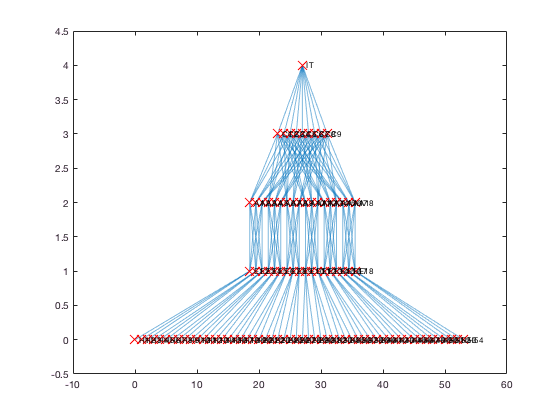

G=graph(EdgeTable,NodeTable);
plotGraphtopology(G);